% Definisco le Matrici
A = [1.14, -0.49, 0.12; 
     1.1, 0, 0;
     0, 1.1, 0]

A =     1.1400   -0.4900    0.1200
    1.1000         0         0
         0    1.1000         0


B = [-0.39; 0.49; 0.53]

B =    -0.3900
    0.4900
    0.5300


C = [1, 0, 0]

C =      1     0     0


D = 0

D = 0

% definizione del sistema nello spazio di stato
sys_ol = ss(A,B,C,D)

sys_ol =
 
  A = 
          x1     x2     x3
   x1   1.14  -0.49   0.12
   x2    1.1      0      0
   x3      0    1.1      0
 
  B = 
          u1
   x1  -0.39
   x2   0.49
   x3   0.53
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% filtro di Kalman in forma di stato
Plant = ss(A,[B B], C, D, -1, 'inputname', {'u', 'v'}, 'outputname', {'y'})

Plant =
 
  A = 
          x1     x2     x3
   x1   1.14  -0.49   0.12
   x2    1.1      0      0
   x3      0    1.1      0
 
  B = 
           u      v
   x1  -0.39  -0.39
   x2   0.49   0.49
   x3   0.53   0.53
 
  C = 
      x1  x2  x3
   y   1   0   0
 
  D = 
      u  v
   y  0  0
 
Sample time: unspecified
Discrete-time state-space model.




Q = 1;
R = 1;
[Kalmanf, L, P, M] = kalman(Plant, Q, R)

Kalmanf =
 
  A = 
           x1_e    x2_e    x3_e
   x1_e  0.8164   -0.49    0.12
   x2_e    0.71       0       0
   x3_e  -0.117     1.1       0
 
  B = 
              u       y
   x1_e   -0.39  0.3236
   x2_e    0.49    0.39
   x3_e    0.53   0.117
 
  C = 
            x1_e     x2_e     x3_e
   y_e    0.6454        0        0
   x1_e   0.6454        0        0
   x2_e  -0.1064        1        0
   x3_e   0.2376        0        1
 
  D = 
               u        y
   y_e         0   0.3546
   x1_e        0   0.3546
   x2_e        0   0.1064
   x3_e        0  -0.2376
 
Input groups:              
       Name        Channels
    KnownInput        1    
    Measurement       2    
                           
Output groups:                
         Name         Channels
    OutputEstimate       1    
    StateEstimate      2,3,4  
                              
Sample time: unspecified
Discrete-time state-space model.



L =     0.3236
    0.3900
    0.1170


P =     0.5493    0.1648   -0.3681
    0.1648    0.6691    0.3884
   -0.3681    0.3884    1.0693


M =     0.3546
    0.1064
   -0.2376


Kalmanf = Kalmanf(1,:)

Kalmanf =
 
  A = 
           x1_e    x2_e    x3_e
   x1_e  0.8164   -0.49    0.12
   x2_e    0.71       0       0
   x3_e  -0.117     1.1       0
 
  B = 
              u       y
   x1_e   -0.39  0.3236
   x2_e    0.49    0.39
   x3_e    0.53   0.117
 
  C = 
          x1_e    x2_e    x3_e
   y_e  0.6454       0       0
 
  D = 
             u       y
   y_e       0  0.3546
 
Input groups:              
       Name        Channels
    KnownInput        1    
    Measurement       2    
                           
Output groups:                
         Name         Channels
    OutputEstimate       1    
                              
Sample time: unspecified
Discrete-time state-space model.



a=A; b=[B,B,0*B]; c=[C;C]; d=[0,0,0;0,0,1];
plant = ss(a,b,c,d,-1, 'inputname', {'u', 'w', 'v'}, 'outputname', {'y', 'yv'})

plant =
 
  A = 
          x1     x2     x3
   x1   1.14  -0.49   0.12
   x2    1.1      0      0
   x3      0    1.1      0
 
  B = 
           u      w      v
   x1  -0.39  -0.39      0
   x2   0.49   0.49      0
   x3   0.53   0.53      0
 
  C = 
       x1  x2  x3
   y    1   0   0
   yv   1   0   0
 
  D = 
       u  w  v
   y   0  0  0
   yv  0  0  1
 
Sample time: unspecified
Discrete-time state-space model.



sys = parallel(plant,Kalmanf,1,1,[],[]);

SimModel = feedback(sys,1,4,2,1)

SimModel =
 
  A = 
              ?       ?       ?    x1_e    x2_e    x3_e
   ?       1.14   -0.49    0.12       0       0       0
   ?        1.1       0       0       0       0       0
   ?          0     1.1       0       0       0       0
   x1_e  0.3236       0       0  0.8164   -0.49    0.12
   x2_e    0.39       0       0    0.71       0       0
   x3_e   0.117       0       0  -0.117     1.1       0
 
  B = 
              w       v       u       y
   ?      -0.39       0   -0.39       0
   ?       0.49       0    0.49       0
   ?       0.53       0    0.53       0
   x1_e       0  0.3236   -0.39  0.3236
   x2_e       0    0.39    0.49    0.39
   x3_e       0   0.117    0.53   0.117
 
  C = 
             ?       ?       ?    x1_e    x2_e    x3_e
   y         1       0       0       0       0       0
   yv        1       0       0       0       0       0
   y_e  0.3546       0       0  0.6454       0       0
 
  D = 
             w       v       u       y
   y         0       0

SimModel = SimModel([1,3],[1,2,3]);

SimModel.Inputname

ans = 3×1 cell array
    {'w'}
    {'v'}
    {'u'}


SimModel.OutputName

ans = 2×1 cell array
    {'y'  }
    {'y_e'}


% Simulazione comportamento del filtro
t = [0:0.01:100]'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


u = sin(t/5)

u =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180


n = length(t)

n = 10001

rng default;
w = sqrt(Q)*randn(n,1)

w =     0.5377
    1.8339
   -2.2588
    0.8622
    0.3188
   -1.3077
   -0.4336
    0.3426
    3.5784
    2.7694


v = sqrt(R)*randn(n,1)

v =    -0.1311
   -0.7686
    2.3900
    0.0772
    0.3756
    0.3956
   -0.1125
   -1.8290
    2.0915
    0.3591


[out, T, x] = lsim(SimModel, [w,v,u]);
y = out(:,1)

y =          0
   -0.2097
   -1.0499
   -0.4938
    0.1507
   -0.1410
    0.1909
    0.7301
    0.5603
   -1.2190


ye = out(:,2);
yv = y+v

yv =    -0.1311
   -0.9783
    1.3400
   -0.4165
    0.5263
    0.2545
    0.0784
   -1.0989
    2.6518
   -0.8599


u_t=[t,u];
w_t=[t,w];
v_t=[t,v];

MeasErr = y -yv % errore di misura

MeasErr =     0.1311
    0.7686
   -2.3900
   -0.0772
   -0.3756
   -0.3956
    0.1125
    1.8290
   -2.0915
   -0.3591


EstErr = y-ye %errore di stima

EstErr =     0.0465
    0.1646
   -1.3129
   -0.5688
   -0.0175
   -0.3152
    0.0910
    1.0921
   -0.1498
   -1.3999


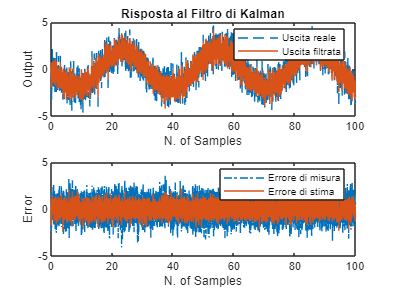

% Visualizzo il confronto tra l'errore di stima e quello di misura
figure(1);
subplot(211), plot(t, y,'--',t,ye,'-'),legend('Uscita reale','Uscita filtrata'), xlabel('N. of Samples'), ylabel('Output'), title('Risposta al Filtro di Kalman');
subplot(212), plot(t, MeasErr, '-.', t, EstErr, '-'), legend('Errore di misura', 'Errore di stima'), xlabel('N. of Samples'), ylabel('Error');

% Calcolo coverianza errore di stia e di misura
MeasErrCov = sum(MeasErr.*MeasErr)/length(MeasErr)

MeasErrCov = 0.9794


EstErrCov = sum(EstErr.*EstErr)/length(EstErr)

EstErrCov = 0.3610